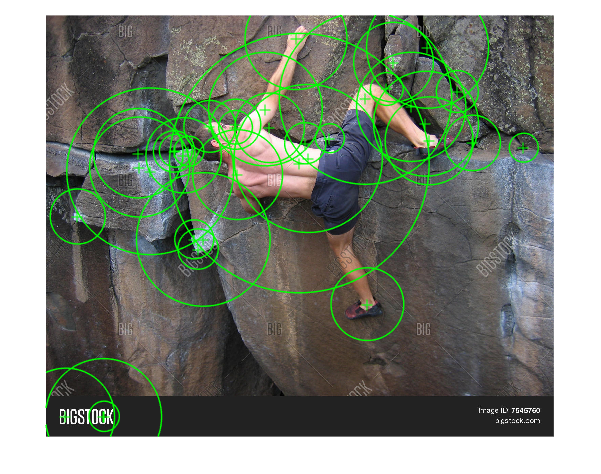

% Load the image
img = imread('rock_climbing.jpg'); % Replace with your image file

% Convert the image to grayscale if it's not already
grayImg = rgb2gray(img);
MinContrast = 0.02;   % Minimum contrast threshold (higher means fewer keypoints)
NumOctaves = 7;       % Number of octaves for scale-space (higher value captures more scales)
sigma =10;
% Detect SIFT features with specified parameters
points = detectSIFTFeatures(grayImg, "NumLayersInOctave",NumOctaves, "ContrastThreshold",MinContrast, Sigma= sigma);
% Extract feature descriptors at the detected keypoints
[features, validPoints] = extractFeatures(grayImg, points);

figure;
imshow(img);
hold on;

plot(validPoints)

hold off

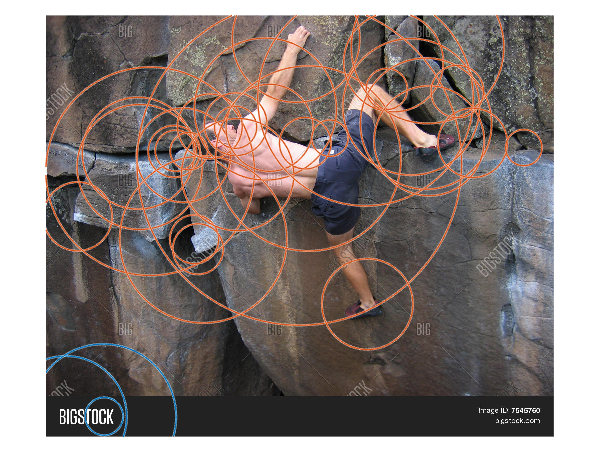


% Initialize clustering
numKeypoints = validPoints.Count;
clusterLabels = zeros(numKeypoints, 1); % Array to store cluster assignments
numClusters = 0; % Counter for number of clusters



for i = 1:numKeypoints
    if clusterLabels(i) == 0  % If the keypoint is not yet assigned
        % Look for similar clusters that are already assigned
        assignedCluster = 0;
        for k = 1:numKeypoints
            if clusterLabels(k) ~= 0  % Check if a previous keypoint is assigned
                similarity = sift_similarity(validPoints, i, k, sigma);
                if similarity == 1  % If similar, take the assigned cluster label
                    clusterLabels(i) = clusterLabels(k);
                    assignedCluster = 1;  % Mark as assigned
                    break;  % Exit the loop once a similar cluster is found
                end
            end
        end
        
        
        % If no similar cluster was found, create a new cluster
        if assignedCluster == 0
            numClusters = numClusters + 1;  % Create a new cluster
            clusterLabels(i) = numClusters;
            
            % Assign similar keypoints to the same new cluster
            for j = 1:numKeypoints
                if clusterLabels(j) == 0  % If not already assigned
                    similarity = sift_similarity(validPoints, i, j,sigma);
                    if similarity == 1  % If similar, assign the same cluster
                        clusterLabels(j) = clusterLabels(i);
                    end
                end
            end
        end
    end
end


% Display the original image with clustered keypoints
figure;
imshow(img);
hold on;
colors = lines(numClusters);
for i = 1:numKeypoints
    % Extract keypoint position, scale, and orientation
    x = validPoints.Location(i, 1); % X-coordinate of the i-th keypoint
    y = validPoints.Location(i, 2); % Y-coordinate of the i-th keypoint
    scale = validPoints.Scale(i);    % Scale of the i-th keypoint
    % Draw the keypoint as a circle
    viscircles([x, y], sigma*scale, 'EdgeColor', colors(clusterLabels(i),:), 'LineWidth', 0.1);

end


hold off;


% Find the frequency of each cluster label
[uniqueLabels, ~, labelIndices] = unique(clusterLabels); % Get unique labels and indices
labelCounts = histcounts(labelIndices, length(uniqueLabels)); % Count occurrences of each unique label

% Find the cluster label with the highest frequency
[maxCount, maxIndex] = max(labelCounts);
mostFrequentCluster = uniqueLabels(maxIndex);

% Display the result
disp(['The most frequent cluster label is: ', num2str(mostFrequentCluster)]);

The most frequent cluster label is: 2


disp(['It appears ', num2str(maxCount), ' times.']);

It appears 51 times.



[imageWidth, imageHeight] = size(grayImg); 

% Cluster label (example: we want the extremities for cluster 1)
clusterId = mostFrequentCluster;

% Find the indices of keypoints belonging to the specified cluster
clusterIndices = find(clusterLabels == clusterId);

% Get the coordinates (x, y) of the keypoints in the specified cluster
xCoords = validPoints.Location(clusterIndices, 1);  % x-coordinates
yCoords = validPoints.Location(clusterIndices, 2);  % y-coordinates
Radii = sigma* validPoints.Scale(clusterIndices);
% Find the extremities (top, bottom, left, right)
top = max(min(yCoords-Radii), 1);  % Ensure top does not go below 1
bottom = min(max(yCoords+Radii), imageHeight);  % Ensure bottom does not exceed image height
left = max(min(xCoords-Radii), 1);  % Ensure left does not go below 1
right = min(max(xCoords+Radii), imageWidth);  % Ensure right does not exceed image width

% Display the result
disp(['Cluster ', num2str(clusterId), ' extremities:']);

Cluster 2 extremities:


disp(['Top: ', num2str(top)]);

Top: 1


disp(['Bottom: ', num2str(bottom)]);

Bottom: 988.2397


disp(['Left: ', num2str(left)]);

Left: 1


disp(['Right: ', num2str(right)]);

Right: 1245


[sticks_imgcoor] = PoseEstimStillImage(pwd, '/', 'rock_climbing.jpg', 1, 'full', [1 1 987 1244]', fghigh_params, parse_params_Buffy3and4andPascal, [], pm2segms_params, true);